# Lab 2

Analysing different physiological and pyschological phenomenons related to vision, colour perception and how brains interpret images.

# Part 1 - Visual Experiments on Perception 

## Task 1

Leave for later

## Task 2 - Ishihara Colour Test

The Ishihara test is a colour vision test designed to detect deficiencies in the long and medium cones. It consists of one set of pictures containing colour dots with a number embedded within. Your goal is to identify the number you see in each of them.

Plates:

74 (Y), 6 (Y), 16 (Y), 2 (Y), 29 (Y), 7 (Y), 45 (Y), 5 (Y), 97 (Y), 8 (Y), 42 (Y), 3 (Y)

> Do these plates identify different kinds of colour blindness?

## Task 3 - Reverse Colour

> Why does this happen?

## Task 4 - Troxler's Fading

Opponent Process Theory

Here is another example to demonstrate the Opponent Process Theory. Play the video [here](http://www.ee.ic.ac.uk/pcheung/teaching/DE4_DVS/assets/purple_dots.mp4) and follow the instruction.

Write down in your logbook the reason of what you see. Read the wikipedia page on Troxler's fading [here](https://en.wikipedia.org/wiki/Troxler%27s_fading), which explains this phenomenon and relates it to the human visual system.

- Relates to neural adaption - unvarying stimuli soon disappear from our awareness

- For example, if a small piece of paper is dropped on the inside of one's forearm, it is felt for a short period of time. Soon, however, the sensation fades away. This is because the tactile neurons have adapted and start to ignore the unimportant stimulus. 

- This is perhaps a survival mechanism to focus on important stimuli that may present a threat?

Troxler's fading can occur without any extraordinary stabilization of the retinal image in [peripheral vision](https://en.wikipedia.org/wiki/Peripheral_vision) because the neurons in the visual system beyond the rods and cones have large [receptive fields](https://en.wikipedia.org/wiki/Receptive_field). This means that the small, involuntary [eye movements](https://en.wikipedia.org/wiki/Eye_movement_(sensory)) made when fixating on something fail to move the stimulus onto a new cell's receptive field, in effect giving unvarying stimulation.

## Task 5 - Brain sees what it expects

- The blue table appears longer however when measuring the onscreen distance the lengths are actually identical - this is likely because of the percieved perspective of the blue table 

A appears to be darker - however when you put the two cells next to each other you can see they are an identical colour - this links to the idea that relative colours appear different in different contexts

> What is the scientific reasoning behind this?

## Task 6 - Grid Illusion

> Read more about it here: [https://en.wikipedia.org/wiki/Grid_illusion](https://en.wikipedia.org/wiki/Grid_illusion)

## Task 7 - Cafe Wall Illusion

When observing the image the lines do not appear parallel - however when you measure out the distances they are equal. 

> Why does this illusion not happen when the contrast is lower?

> Read more about it here: [https://en.wikipedia.org/wiki/Caf%C3%A9_wall_illusion](https://en.wikipedia.org/wiki/Caf%C3%A9_wall_illusion)

## Task 8 - the Silhouette Illusion

Explanation: [https://en.wikipedia.org/wiki/Spinning_dancer](https://en.wikipedia.org/wiki/Spinning_dancer)

## Task 9 - the Incomplete Triangles

There are no complete triangles in the image - but there may be an illusion of a white triangle in the centre.

The last task in part 1 is to consider the picture below. How many triangles are in the picture? What conclusions can you draw from this observation?

# Part 2 - Colour Spaces

## Task 10 - Convert RGB image to Grayscale

imfinfo('inputs/peppers.png')

ans = struct with fields:
                  Filename: '/Users/marci/Documents/GitHub/DVS/inputs/peppers.png'
               FileModDate: '13-Feb-2026 03:02:06'
                  FileSize: 711722
                    Format: 'png'
             FormatVersion: []
                     Width: 777
                    Height: 584
                  BitDepth: 24
                 ColorType: 'truecolor'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: []
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'alpha'
    SimpleTransparencyData: []
           BackgroundColor: []
           RenderingIntent: []
            Chromaticities: []
                     Gamma: []
               XResolution: []
               YResolution: []
            ResolutionUnit: []
                   XOffset: []
                   YOffset: []
                OffsetUnit: []
           SignificantBits: []
              ImageModTime: []
              

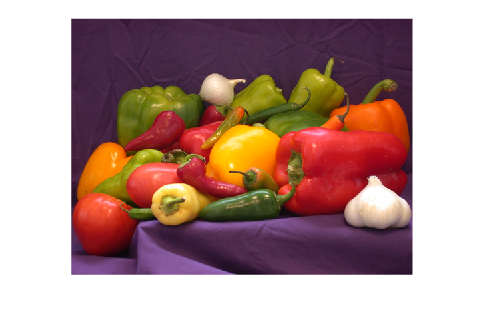


RGB = imread('peppers.png');  
imshow(RGB);

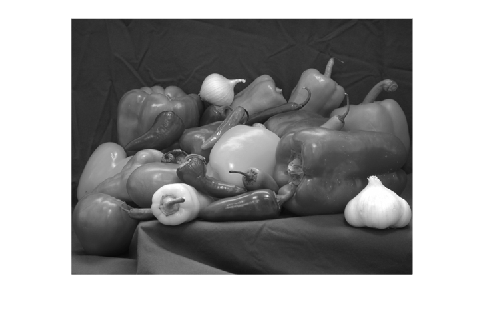


I = rgb2gray(RGB);         
imshow(I);

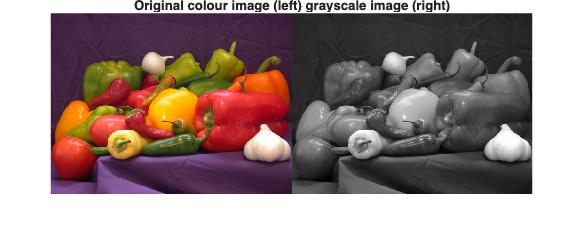


figure;
imshowpair(RGB, I, 'montage');
title('Original colour image (left) grayscale image (right)');

Images may be converted to greyscale as this is easier to process.

> How do you perform these calculations - e.g. explored in later labs - on colour images?

> How do you perform these transformations manually e.g. without matlabs built in functions?

> Where do the numbers for these conversions come from?

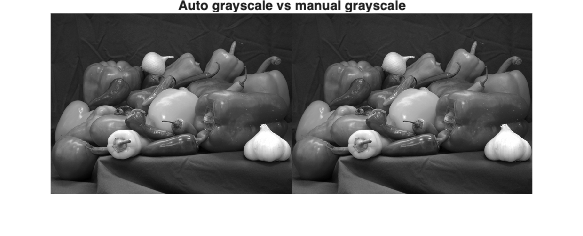

[R,G,B] = imsplit(RGB);
I2 = 0.299 * R + 0.587 * G + 0.114 * B;
% you can see that performing this manually also works!
figure;
imshowpair(I, I2, 'montage')
title('Auto grayscale vs manual grayscale');

## Task 11 - Splitting an RGB image into separate channels

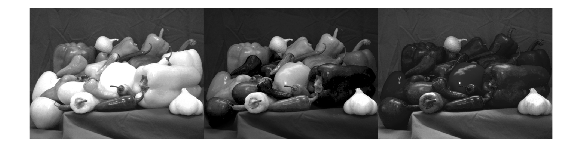

RGB = imread('inputs/peppers.png');  
[R,G,B] = imsplit(RGB);
montage({R, G, B},'Size',[1 3])

Note the following: Red peppers have a signal predominantly in the red channel. Yellow and green peppers have a signal in both the red and green channels. White objects, such as the garlic in the foreground, have a strong signal in all three channels.

**B is much lower than R - which can be seen as the overall image is a lot darker. Red is the most prominent colour in the image.**

Examine the information shown on the right side of the Matlab window. Explain their dimensions and data type of the variables RGB, R, G, B and I. 

R, G, B are all `uint8` which means they are integers not floating points - sometimes this makes some operations more difficult to perform. I is also a `uint8`

They all also have the same size 384x512 - the size of the image.

## Task 12 - Map RGB image to HSV space and into separate channels

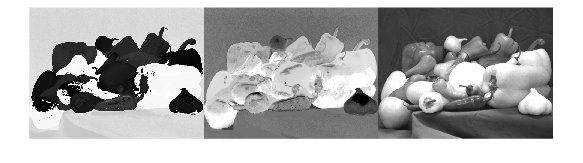

RGB = imread('inputs/peppers.png');  
HSV = rgb2hsv(RGB);
[H,S,V] = imsplit(HSV);
montage({H,S,V}, 'Size', [1 3])

Hue - relatively consistent across the different peppers - with slight variations e.g. between red, yellow and green peppers

Saturation - relatively consistent across the different peppers

Value - corresponds to how light or dark the image is 

> How to do this by hand instead?

## Task 13 - Map RGB image to XYZ space

Map the RGB image to the XYZ colour space with the rgb2xyz( ) function

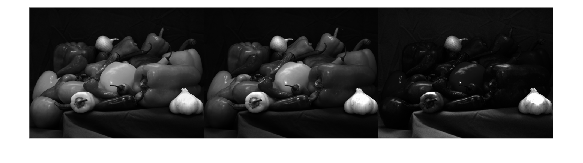

RGB = imread('inputs/peppers.png');  
XYZ = rgb2xyz(RGB);
[X,Y,Z] = imsplit(XYZ);
montage({X,Y,Z}, 'Size', [1 3])

Aligns with CIE colour space theory - it corresponds more with human visual perception

Z is much darker than X and Y for this image - because bluer hues are less present in this image which has a warm colour.